Préliminaire 1

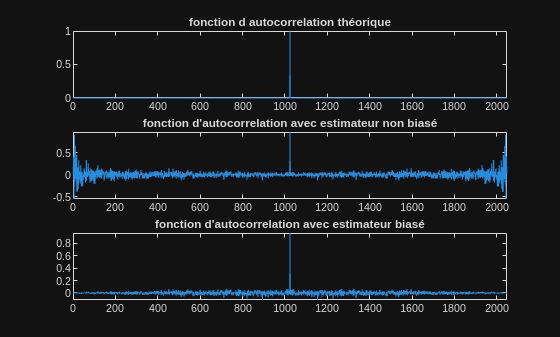

clc; close all; clear;

%parameters
N=1024;
fn = -1/2:1/N:1/2-1/N;
sigma2 = 1;
m = 0;
Fe = 1000; %en Hz

b = sqrt(sigma2)*randn(1,N) + m;

% fonction d'autocorrelation
[Rxx_biased, lags] = xcorr(b, 'biased');
Rxx_theo = sigma2 * (lags == 0);
Rxx_unbiased = xcorr(b,'unbiased');

figure
subplot(3,1,1)
plot(Rxx_theo)
axis([0 2*N min(Rxx_theo) max(Rxx_theo)]);
title('fonction d autocorrelation théorique')

subplot(3,1,2)
plot(Rxx_unbiased)
axis([0 2*N min(Rxx_unbiased) max(Rxx_unbiased)]);
title("fonction d'autocorrelation avec estimateur non biasé")

subplot(3,1,3)
plot(Rxx_biased)
axis([0 2*N min(Rxx_biased) max(Rxx_biased)]);
title("fonction d'autocorrelation avec estimateur biasé")

On voit que pour l'estimateur non biaisé aux extremités on a de plus en plus de variations. En effet aux extrémités on a de moins en moins de valeur donc de plus grandes variations. On remarque également que pour l'estimateur biaisé on a des variations lié au fait qu'on a un bruit doonc qu'on a des variations.

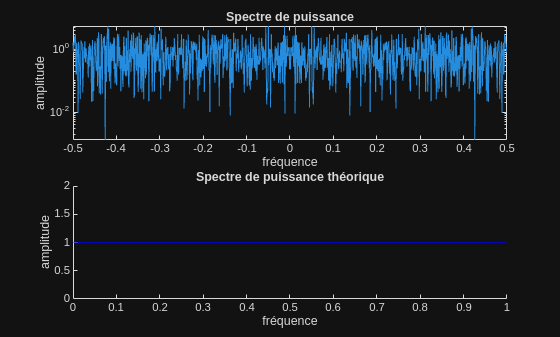

% Spectre de puissance
B=fftshift(fft(b));
DSP = (abs(B).^2)/N;
DSP_theo = sigma2;

figure
subplot(2,1,1)
semilogy(fn, DSP)
title('Spectre de puissance')
xlabel('fréquence')
ylabel('amplitude')
subplot(2,1,2)
yline(DSP_theo,'-b');
title('Spectre de puissance théorique')
xlabel('fréquence')
ylabel('amplitude')

Le spectre de puissance réel vari, mais reste cependant au alentour de la valeur théorique : 1. Cela s'explique car le bruit n'a pas une amplitude constante donc cela se repercute sur le spectre de puissance.

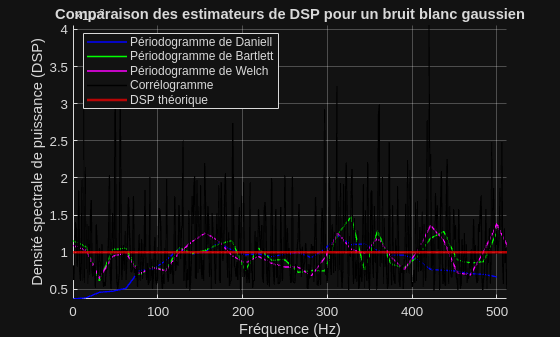

%Comparaison des periodogramme
NFFT = 64;
nr = 32;
fenetre = 16;
M = 128;

[PSD_daniell, f_daniell] = Mon_Daniell(b, NFFT, Fe, fenetre);

[PSD_bartlett, f_bartlett] = Mon_Bartlett(b, NFFT, Fe);

[PSD_welch, f_welch] = Mon_Welch(b, NFFT, Fe, nr);

DSP_theo_normalise = sigma2 / Fe;

[Rxx_biased, lags] = xcorr(b, 'biased');
Rxx_pos = Rxx_biased(lags >= 0); % partie positive
PSD_corr = abs(fft(Rxx_pos, N));
f_corr = (0:N-1) * Fe / N;
PSD_corr_norma = PSD_corr / Fe; 

figure;
hold on;
plot(f_daniell, PSD_daniell, 'b', 'LineWidth', 1);
plot(f_bartlett, PSD_bartlett, 'g', 'LineWidth', 1);
plot(f_welch, PSD_welch, 'm', 'LineWidth', 1);
plot(f_corr, PSD_corr_norma, 'k', 'LineWidth', 1);
axis([0 N/2 min(PSD_daniell) max(PSD_corr_norma)]);
yline(DSP_theo_normalise, 'r', 'LineWidth', 2);

title('Comparaison des estimateurs de DSP pour un bruit blanc gaussien');
xlabel('Fréquence (Hz)');
ylabel('Densité spectrale de puissance (DSP)');
legend('Périodogramme de Daniell', ...
       'Périodogramme de Bartlett', ...
       'Périodogramme de Welch', ...
       'Corrélogramme', ...
       'DSP théorique', ...
       'Location', 'best');
grid on;
hold off;

%calcul de la platitude spectrale
N_it = 10;
p = 3;

tab_platitude = zeros(1,N_it);
tab_p_platitude = zeros(1,N_it);
tab_platitude_welch = zeros(1,N_it);

for k = 1 : N_it
    b = sqrt(sigma2)*randn(1,N) + m;
    B=fftshift(fft(b));
    DSP = (abs(B).^2)/N;
    [PSD_welch, f_welch] = Mon_Welch(b, NFFT, Fe, nr);

    moy_ari = mean(DSP);
    moy_geo = geomean(DSP);
    moy_p = (mean(DSP.^p)).^(1/p);                  

    moy_ari_welch = mean(PSD_welch);
    moy_geo_welch = geomean(PSD_welch);

    tab_platitude(k) = moy_geo/moy_ari;
    tab_p_platitude(k) = moy_p/moy_ari;
    tab_platitude_welch(k) = moy_geo_welch/moy_ari_welch;
end

moy_platitude = mean(tab_platitude);
moy_p_platitude = mean(tab_p_platitude);

ecart_type_platitude = std(tab_platitude);

moy_platitude_welch = mean(tab_platitude_welch);
ecart_type_platitude_welch = std(tab_platitude_welch);

fprintf('Platitude spectrale (1re réalisation) : %.4f\n', tab_platitude(1));

Platitude spectrale (1re réalisation) : 0.5613


fprintf('Platitude spectrale moyenne : %.4f\n',moy_platitude);

Platitude spectrale moyenne : 0.5621


fprintf('Platitude spectrale moyenne à l ordre p : %.4f\n',moy_p_platitude);

Platitude spectrale moyenne à l ordre p : 1.7879


fprintf('Ecart type de la platitude : %.4f\n',ecart_type_platitude);

Ecart type de la platitude : 0.0191


fprintf('Platitude spectrale moyenne avec Welch : %.4f\n', moy_platitude_welch);

Platitude spectrale moyenne avec Welch : 0.9850


fprintf('Ecart type de la platitude avec Welch: %.4f\n',ecart_type_platitude_welch);

Ecart type de la platitude avec Welch: 0.0033


La valeur théroique devrait etre de 1 car la moyenne géométrique et la moyenne arithmétique sont égale à sigma carré

Préliminaire 2

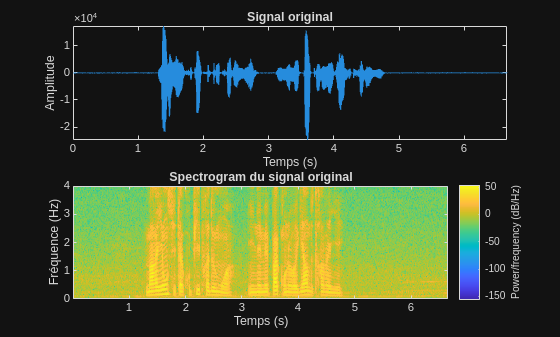

% Chargement des données et paramètres
data = load('fcno03fz.mat');
s = data.fcno03fz(:);
N = length(s);
n = (0:N-1) / 8000;  % echantillonage de 44100 hz car signal de parole

% Génération des signaux bruités
bruit5 = generer_bruits(s, 5);
s_bruit5 = s + bruit5;

bruit10 = generer_bruits(s, 10);
s_bruit10 = s + bruit10;

bruit15 = generer_bruits(s, 15);
s_bruit15 = s + bruit15;

% Figure pour le signal original
figure()
subplot(2, 1, 1)
plot(n, s)
title('Signal original')
xlabel('Temps (s)')
ylabel('Amplitude')
xlim([0 max(n)]);
ylim([min(s) max(s)]);

subplot(2, 1, 2)
spectrogram(s, 256, [], [], 8000, 'yaxis');

title('Spectrogram du signal original')
xlabel('Temps (s)')
ylabel('Fréquence (Hz)');

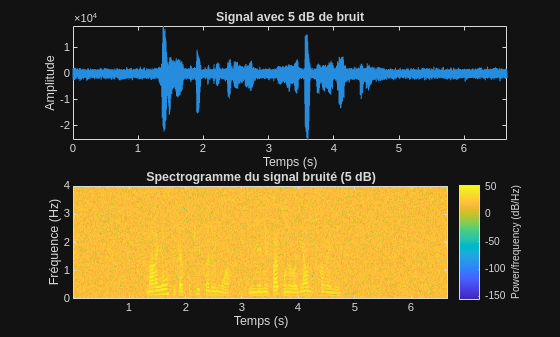


% Figure pour le signal bruité (par exemple avec 5 dB de bruit)
figure()
subplot(2, 1, 1)
plot(n, s_bruit5)
title('Signal avec 5 dB de bruit')
xlabel('Temps (s)')
ylabel('Amplitude')
xlim([0 max(n)]);
ylim([min(s_bruit5) max(s_bruit5)]);

subplot(2, 1, 2)
spectrogram(s_bruit5, 256, [], [], 8000, 'yaxis');
title('Spectrogramme du signal bruité (5 dB)')
xlabel('Temps (s)')
ylabel('Fréquence (Hz)');

avec un bruit de 5 db

Le bruit domine.

Les structures du signal de parole sont **fortement atténuées** 

Le spectrogramme devient plus uniforme, avec moins de contraste entre les zones de forte et faible énergie.

Dans l’ensemble, plus le RSB diminue, plus le spectrogramme perd en lisibilité et en contraste. Cela reflète une dégradation progressive du signal utile, confirmée à l’écoute par une baisse de la qualité perçue.

préliminaire 3

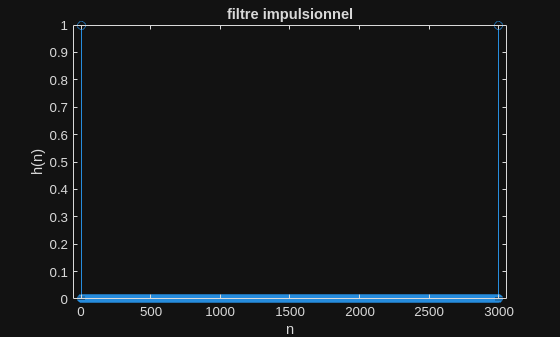

data = load('fcno03fz.mat');
s = data.fcno03fz(:);
N = length(s);
n = (0:N-1) / 8000;
k = [1 10 100 300 3000 10000];
k0=k(5);
h1 = filtre_impulsionnel(k0);

figure()
stem(0:k0, h1)
title('filtre impulsionnel')
xlabel('n')
ylabel('h(n)')

caractèrisation du filtre h(𝑘) = $\delta \left(k\right)+\delta \left(k-\textrm{k0}\right)$ :

     - RIF ( que 2 échantillons non nul)

    - Causal (h est non nul que pour n = 0 et n = n0 > 0

    - Stable car RIF

    - TFZ(h(n)) = H(Z) = $1+Z^{\;-\textrm{k0}}$

    - pas de pôles

    - zero complexe dépendant de k0

zn = $e^{j\pi \frac{2n+1}{\textrm{k0}}}$  avec $\left.m\in \lbrace 0,1,\ldotp \ldotp \ldotp ,\textrm{k0}-1\right\rbrace$

% Figure pour le signal original
figure()
subplot(2, 1, 1)
plot(n, s)
title('Signal original')
xlabel('Temps (s)')
ylabel('Amplitude')
xlim([0 max(n)]);
ylim([min(s) max(s)]);

subplot(2, 1, 2)
spectrogram(s, 256, [], [], 8000, 'yaxis');

title('Spectrogram du signal original')
xlabel('Temps (s)')
ylabel('Fréquence (Hz)');

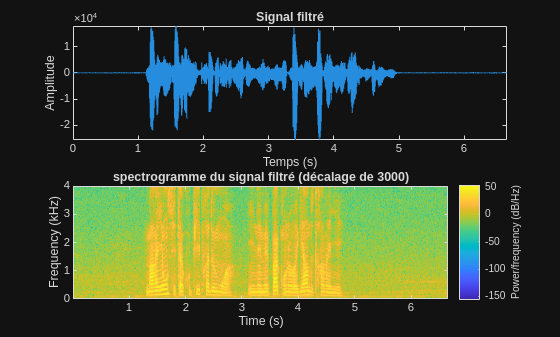


%filtrage
s_filtre = conv(s, h1, 'same');
% Affichage du signal filtré
figure()
subplot(2, 1, 1)
plot(n, s_filtre)
title('Signal filtré')
xlabel('Temps (s)')
ylabel('Amplitude')
xlim([0 max(n)]);
ylim([min(s_filtre) max(s_filtre)]);
subplot(2,1,2)
spectrogram(s, 256, [], [], 8000, 'yaxis');
title('spectrogramme du signal filtré (décalage de 3000)')

écoute pour k = 1, 10, 100, 3 000, 10 000

h = filtre_impulsionnel(1);
s_filtre = conv(s, h1, 'same');
sound(s_filtre,8000);

Préliminaire 4

%chargement du signal
data = load('fcno03fz.mat');
s = data.fcno03fz(:);     
N = length(s);

%parametres
N_t = 256;   %taille trame
recouvrement = 0.5;
step = round(N_t * (1 - recouvrement));
fenetre = hamming(N_t);

%decomposition sans recouvrement
nb_trames_no = floor(N / N_t);

frames_no = reshape(s(1 : nb_trames_no*N_t), N_t, nb_trames_no);
frames_no = frames_no .* fenetre;     

% indices de début sans recouvrement
starts_no = 1:N_t:(nb_trames_no*N_t);

%decomposition avec recouvrement
starts_ov = 1:step:(N - N_t + 1);
nb_trames_ov = length(starts_ov);

frames_ov = zeros(N_t, nb_trames_ov);

for k = 1:nb_trames_ov
    frames_ov(:,k) = s(starts_ov(k) : starts_ov(k)+N_t-1) .* fenetre;
end

%reconstruction sans recouvrement
recon_no = zeros(N,1);

for k = 1:nb_trames_no
    i0 = starts_no(k);
    i1 = i0 + N_t - 1;
    recon_no(i0:i1) = frames_no(:,k);
end

%reconstruction avec recouvrement
recon_ov = zeros(N,1);
win_energy = zeros(N,1);

for k = 1:nb_trames_ov
    i0 = starts_ov(k);
    i1 = i0 + N_t - 1;

    recon_ov(i0:i1) = recon_ov(i0:i1) + frames_ov(:,k);
    win_energy(i0:i1) = win_energy(i0:i1) + fenetre.^2;
end

% normalisation
idx = win_energy > 1e-12;
recon_ov(idx) = recon_ov(idx) ./ win_energy(idx);

%affichage
figure;
subplot(2,1,1)
plot(s,'g'); hold on;
subplot (2,1,2)
plot(recon_no,'r--');
title('Reconstruction SANS recouvrement');
legend('Signal original','Reconstruit');

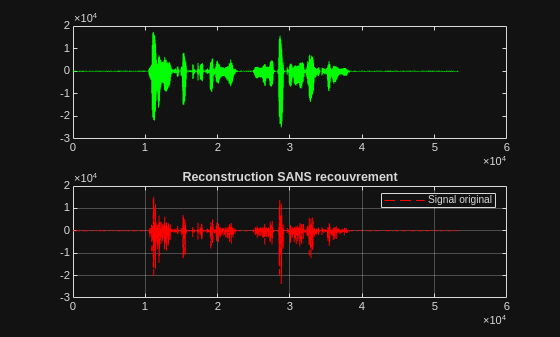

grid on;


figure
subplot(2,1,1)
plot(s,'g'); hold on;
subplot (2,1,2)
plot(recon_ov,'r--');
title('Reconstruction AVEC recouvrement');
legend('Signal original','Reconstruit');

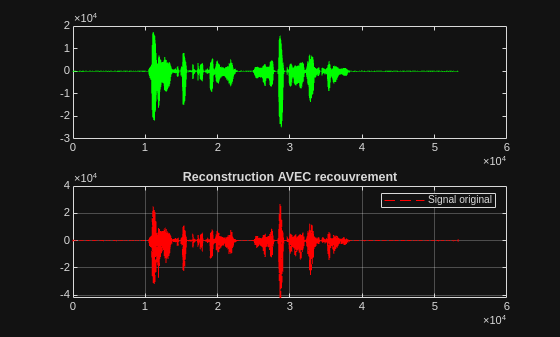

grid on;